## Naïve Bayes Analysis part 2

Analysis & Hyperparameter Search on the dataset here uses the standardised dataset with fewer features. 

Naive Bayes classification is performed using boostrapping, which is recomended for large datasets: the training and testing times are shortest..

Several metrics are calculated for the multiclass naive Bayes classifier: 

- precision, recall, accuracy[1] 

- F1 [2]. 

Training and testing of the training dataset is performed using MATlab's fitcnb and predict functionality [3]. All the kernel smoothing algorithms covered in the MATlab documentation [3] are evaluated.

### This section clears the workspace, loads the dataset

The dataset used is the standardised dataset, the features previously identified as not useful are removed.

% CLear all, load the dataset
clear
clc
clf
close all
% loads the letter dataset 
% 
load letterDatasetClass.mat
letterDataset = letterDatasetStandardised;
letterDataset.removeColumn("xBox");
letterDataset.removeColumn("yBox");
letterDataset.removeColumn("width");
letterDataset.removeColumn("height");
%[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
%X = table2array(X);
%Y = table2array(Y);
disp(letterDataset);

  LetterDatasetClass with properties:

           datasetFilePath: "Dataset/letter-recognition.csv"
         testSetProportion: 0.2000
                randomSeed: 1
                targetName: {'TargetAscii'}
              featureNames: {1×12 cell}
          validClassValues: [26×1 table]
    datasetContentsAsTable: [20000×13 table]
                trainTable: [16000×13 table]
                 testTable: [4000×13 table]
            isStandardised: 1
          isRemovedFeature: 1



## Run Hyperparameter Search

### Using MATLAB's Default 'normal' Distribution Name

The 'normal' distribution name search is used as benchmark check for subsequent searches. 

#### Hyperparameter Search

nBayes = NBayesClass.getDefaultInstanceNoFit(letterDataset);
hyperparameters = NBayesHyperparameterClass.getDefaultTestHyperparametersInstance(nBayes);
startTime = cputime;
results = nBayes.performHyperparameterSearch(hyperparameters, "nBayesDefaultSmootherSearch.csv");
endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

#### Results

results = NBayesResults.getInstanceFromCsvResults("nBayesDefaultSmootherSearch.csv");

Starting Naive Bayes analysis...
Completed NBayes analysis


disp(results.resultsTable);
PlotUtil.plotLossTestTrainComparison(results.resultsTable, "Test Train Loss comparison");
PlotUtil.plotMetrics(results.resultsTable, "Average Result Metrics");

Total cpu time (seconds): 12.8500

PlotUtil.plotTime(results.resultsTable, "Average Time for: Train & Test")

### Using MATLAB's Kernel Distribution Names, All Smoothers and Selected Widths

#### Triangle Smoother Type Hyperparameter Search

nBayes = NBayesClass.getDefaultInstanceNoFit(letterDataset);
hyperparameters = NBayesHyperparameterClass.getKernelTriangleSmootherHyperparametersInstance(nBayes);

    distributionName    smootherType    Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'normal'}        {'unused'}      -1            2                 2               0.34

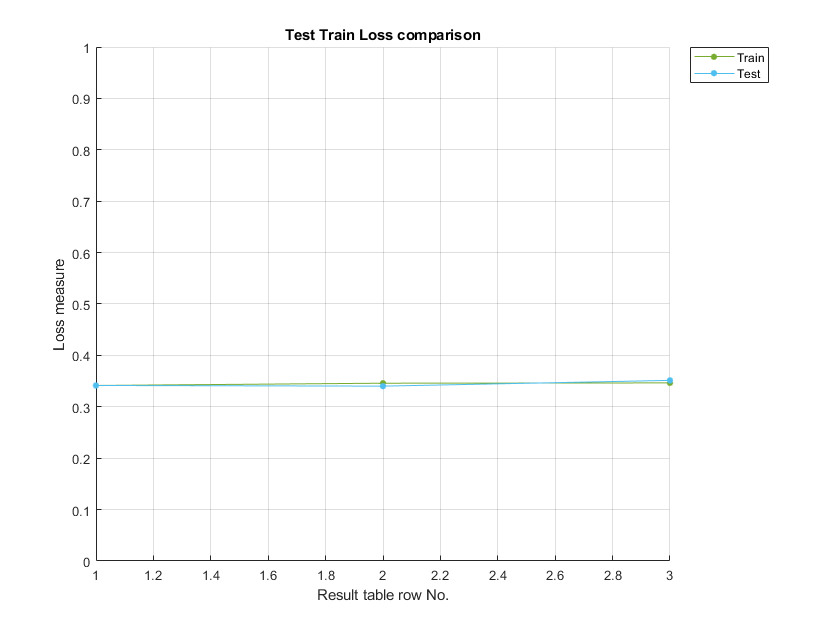

startTime = cputime;

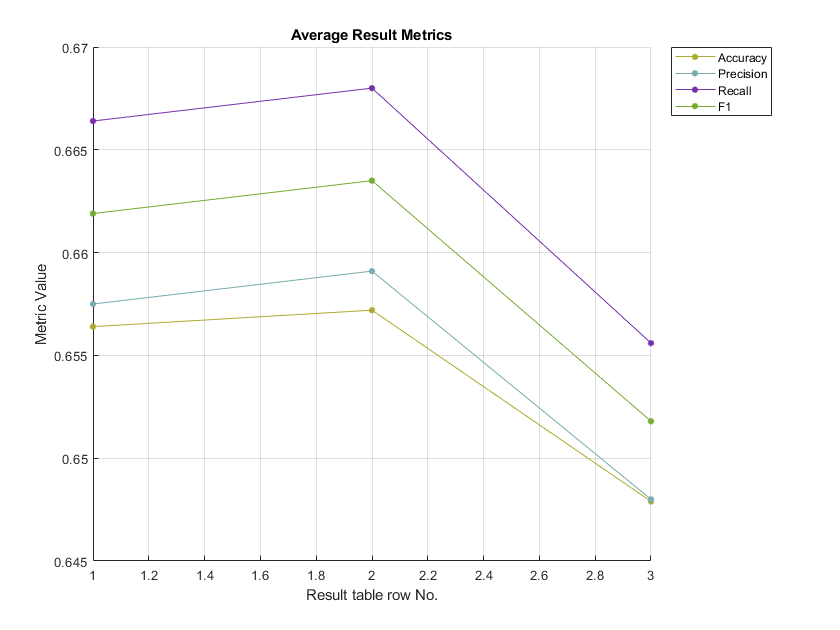

results = nBayes.performHyperparameterSearch(hyperparameters, "nBayesTriangleSmootherSearch.csv");

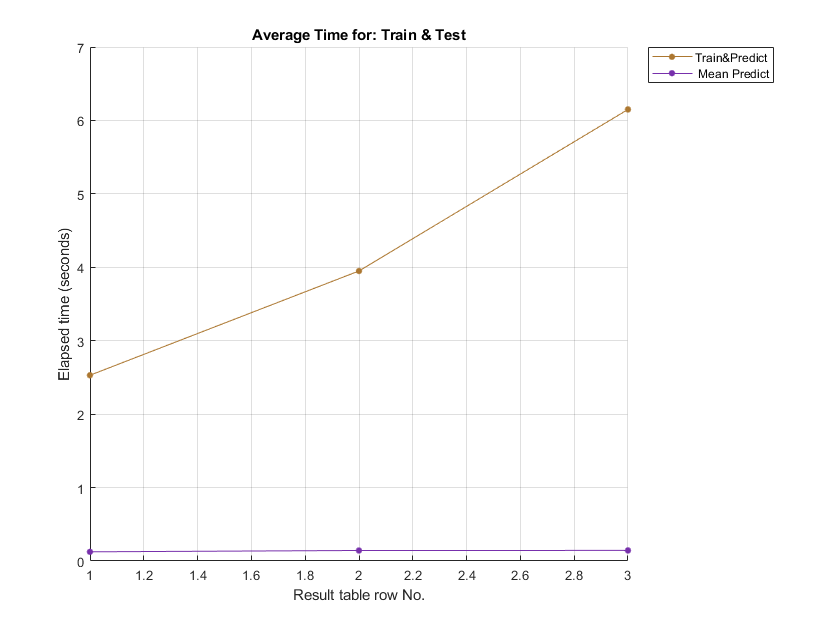

endTime = cputime;

totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

#### Triangle Smoother Type Results

results = NBayesResults.getInstanceFromCsvResults("nBayesTriangleSmootherSearch.csv");
disp(results.resultsTable);
PlotUtil.plotLossTestTrainComparison(results.resultsTable, "Test Train Loss comparison");
PlotUtil.plotMetrics(results.resultsTable, "Average Result Metrics");

Starting Naive Bayes analysis...
Completed NBayes analysis


PlotUtil.plotTime(results.resultsTable, "Average Time for: Train & Test")

The rows that perform best in terms of accuracy are 1, 6, 9, 13, 18

disp(results.resultsTable([1, 6, 9, 13, 18],:))

The quickest also happens to be the best in terms of accuracy, precision, recall and f1 score:

**2 folds, triangle kernel smoother, width 0.098351**

bestTriangle = results.resultsTable([13],:)

Total cpu time (seconds): 3904.2800

#### Normal Smoother Type Hyperparameter Search

nBayes = NBayesClass.getDefaultInstanceNoFit(letterDataset);
hyperparameters = NBayesHyperparameterClass.getKernalNormalSmootherHyperparametersInstance(nBayes);

    distributionName    smootherType     Width      numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    ________    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}       {'triangle'}        0.13          2                 2          

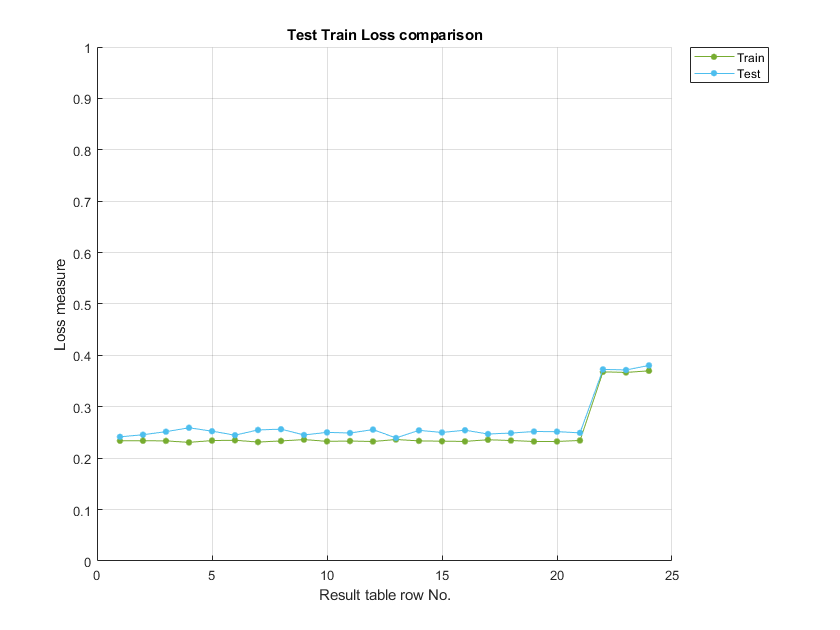

startTime = cputime;

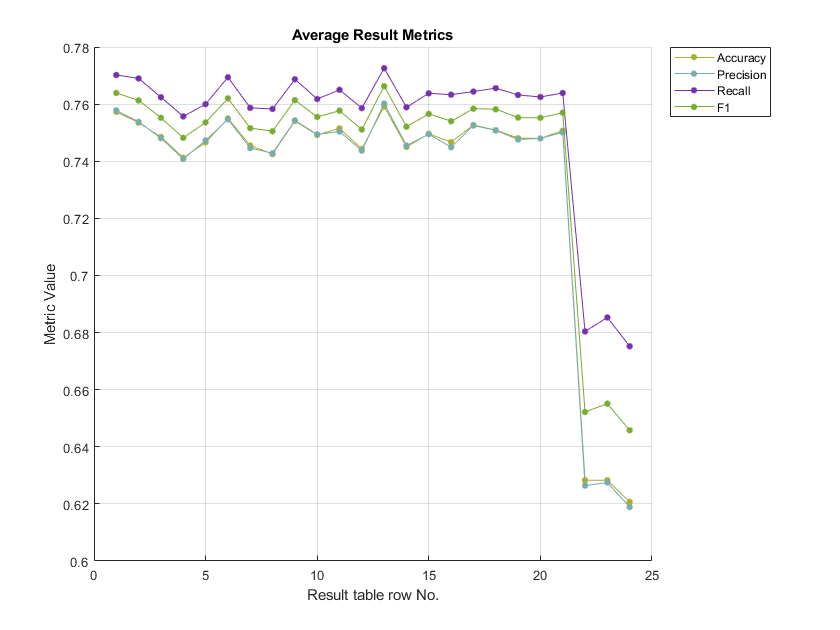

results = nBayes.performHyperparameterSearch(hyperparameters, "nBayesNormalSmootherSearch.csv");

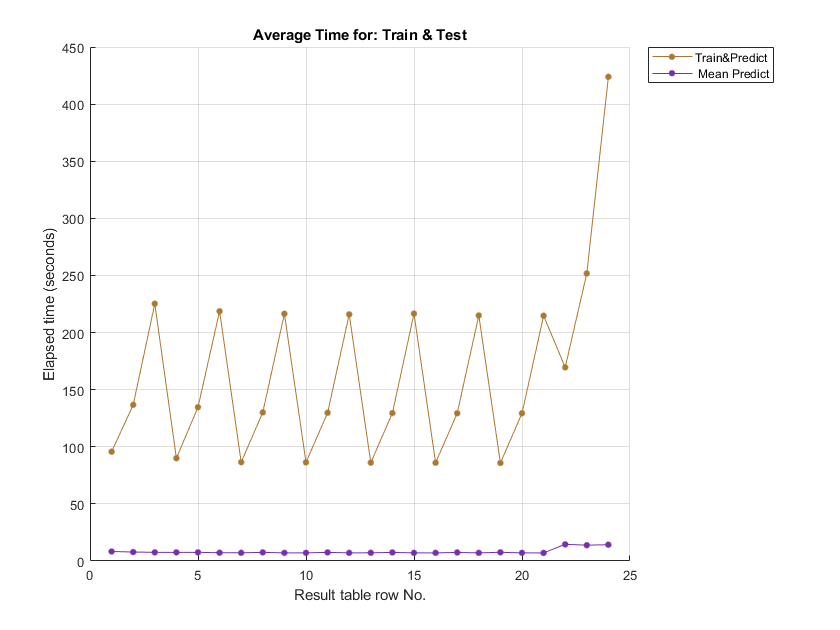

endTime = cputime;

totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

    distributionName    smootherType     Width      numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    ________    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}       {'triangle'}        0.13          2                 2          

#### Normal Smoother Type Results

results = NBayesResults.getInstanceFromCsvResults("nBayesNormalSmootherSearch.csv");

bestTriangle = 1×14 table
    distributionName    smootherType     Width      numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    ________    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}       {'triangle'}    0.098351          2  

disp(results.resultsTable);
PlotUtil.plotLossTestTrainComparison(results.resultsTable, "Test Train Loss comparison");
PlotUtil.plotMetrics(results.resultsTable, "Average Result Metrics");
PlotUtil.plotTime(results.resultsTable, "Average Time for: Train & Test")

In terms of accuracy, row 13 is the best, the quickest times are for rows 13, 16, 19

disp(results.resultsTable([13, 16, 19],:))

The best one takes longer, but only by a matter of a few minutes. The hyperparameters to use here are:

**2 folds, normal kernel smoother, width 0.11**

bestNormal = results.resultsTable([13],:)

#### Epanechnikov Smoother Type Hyperparameter Search

nBayes = NBayesClass.getDefaultInstanceNoFit(letterDataset);

Starting Naive Bayes analysis...
Completed NBayes analysis


hyperparameters = NBayesHyperparameterClass.getKernalEpanechnikovSmootherHyperparametersInstance(nBayes);
startTime = cputime;
results = nBayes.performHyperparameterSearch(hyperparameters, "nBayesEpanechikovSmootherSearch.csv");

Total cpu time (seconds): 6626.0400

endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

#### Epanechnikov Smoother Type Hyperparameter Results

results = NBayesResults.getInstanceFromCsvResults("nBayesEpanechikovSmootherSearch.csv");

    distributionName    smootherType    Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}        {'normal'}      0.2           2                 2               0.24

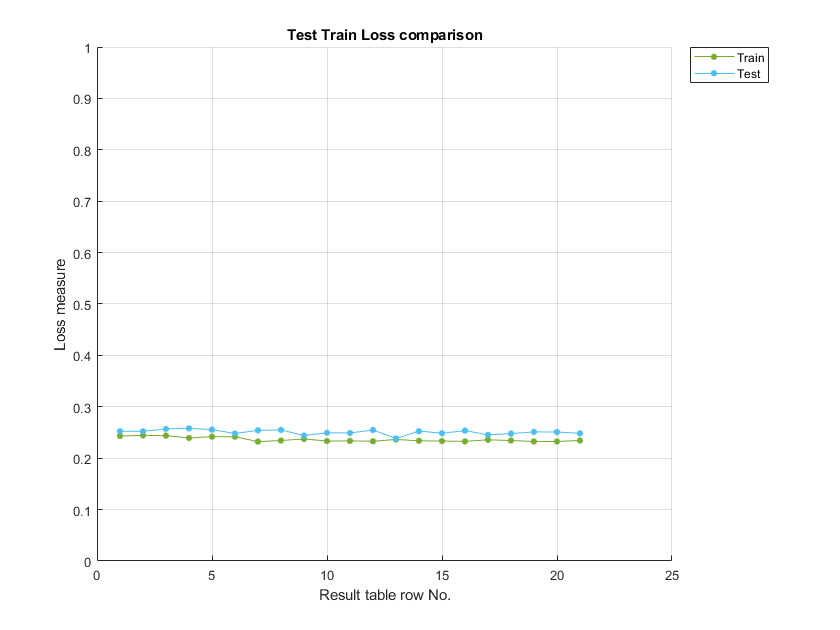

disp(results.resultsTable);

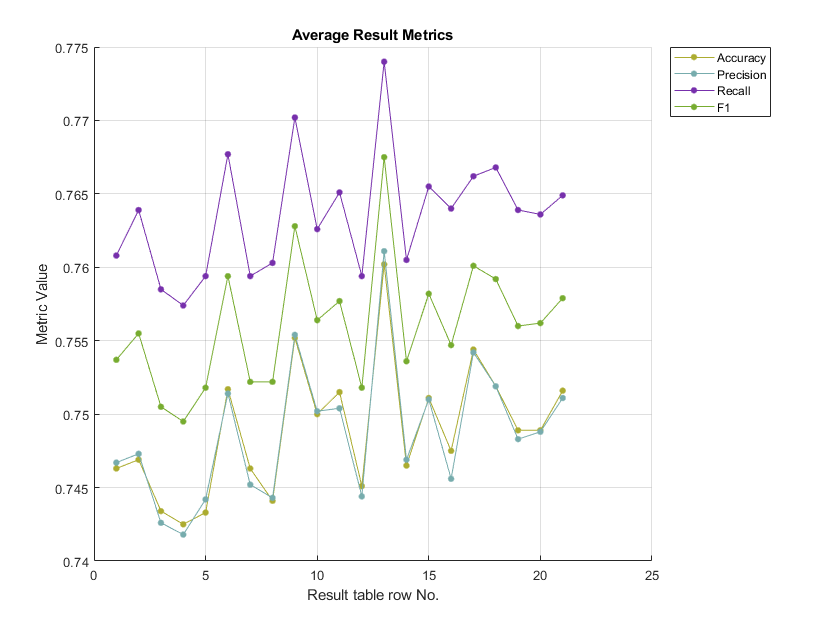

PlotUtil.plotLossTestTrainComparison(results.resultsTable, "Test Train Loss comparison");

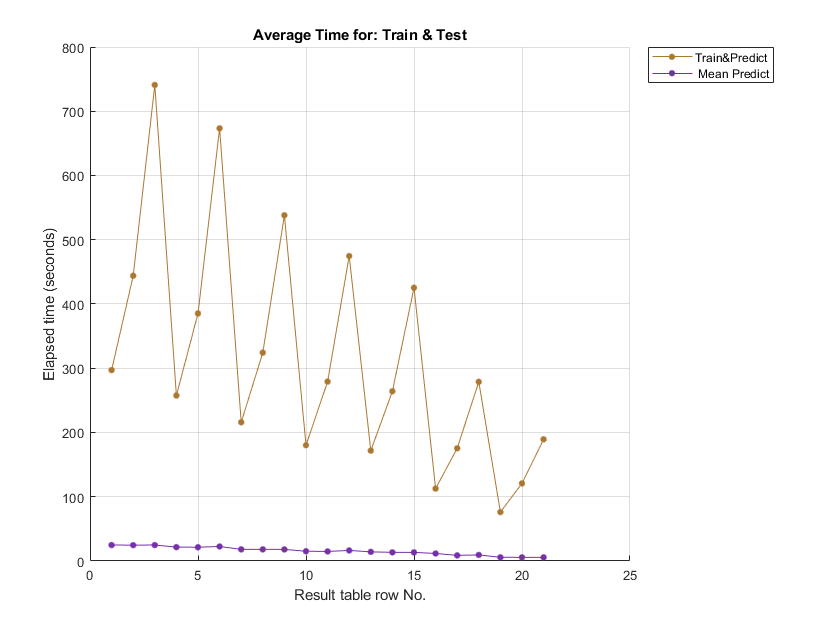

PlotUtil.plotMetrics(results.resultsTable, "Average Result Metrics");

PlotUtil.plotTime(results.resultsTable, "Average Time for: Train & Test")

The rows that perform best in terms of accuracy are 1, 6, 9, 13, 18

disp(results.resultsTable([1, 6, 9, 13, 18],:))

    distributionName    smootherType    Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}        {'normal'}     0.11           2                 2               0.23

The best one is quickest, but only by a matter of a few minutes. The hyperparameters to use here are:

**2 folds, normal kernel smoother, width 0.11**

bestEpanechnikov = results.resultsTable([13],:)

bestNormal = 1×14 table
    distributionName    smootherType    Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}        {'normal'}     0.11           2             

#### Box Smoother Type Hyperparameter Search

nBayes = NBayesClass.getDefaultInstanceNoFit(letterDataset);
hyperparameters = NBayesHyperparameterClass.getKernalBoxSmootherHyperparametersInstance(nBayes);
startTime = cputime;
results = nBayes.performHyperparameterSearch(hyperparameters, "nBayesBoxSmootherSearch.csv");

Starting Naive Bayes analysis...
Completed NBayes analysis


endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 2966.8200

#### Box Smoother Type Hyperparameter Results

results = NBayesResults.getInstanceFromCsvResults("nBayesBoxSmootherSearch.csv");
disp(results.resultsTable);

    distributionName      smootherType      Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ________________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}       {'epanechnikov'}     0.2           2                 2       

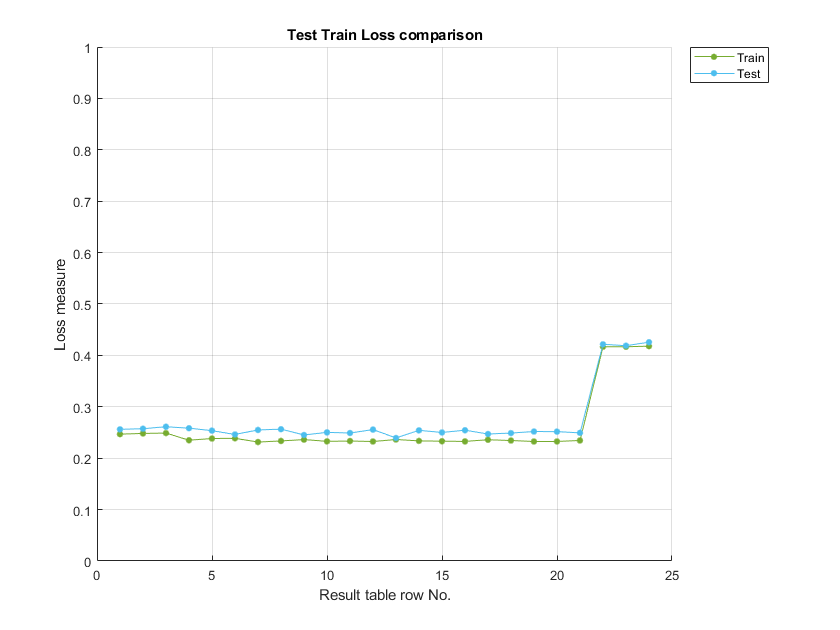

PlotUtil.plotLossTestTrainComparison(results.resultsTable, "Test Train Loss comparison");

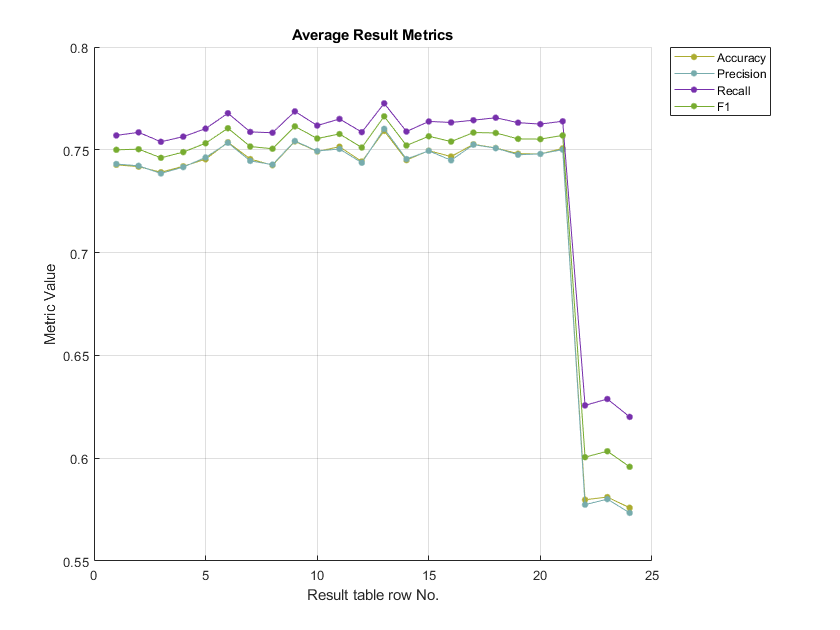

PlotUtil.plotMetrics(results.resultsTable, "Average Result Metrics");

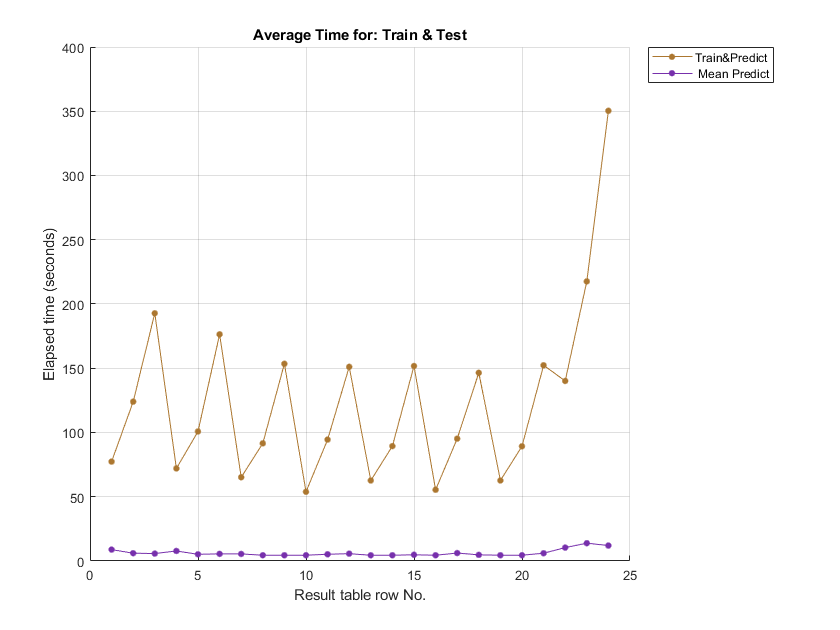

PlotUtil.plotTime(results.resultsTable, "Average Time for: Train & Test")

The rows that perform best in terms of accuracy are 1, 6, 9, 13, 18. 

disp(results.resultsTable([1, 6, 9, 13, 18],:))

    distributionName      smootherType      Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ________________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}       {'epanechnikov'}     0.2           2                 2       

The hyperparameters to use here are:

**2 folds, normal kernel smoother, width 0.11**

bestBox = results.resultsTable([13],:)

bestEpanechnikov = 1×14 table
    distributionName      smootherType      Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ________________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}       {'epanechnikov'}    0.11       

### Final Hyperparameter Choice

bestTable = [bestTriangle(:,:); bestNormal(:,:); bestEpanechnikov(:,:); bestBox(:,:)];
disp(bestTable);

The best, but also slower, is the **normal smoother type with a width of 0.11, random seed 2**. 

Starting Naive Bayes analysis...
Completed NBayes analysis


Total cpu time (seconds): 2576.3200

    distributionName    smootherType    Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}         {'box'}        0.2           2                 2                0.2

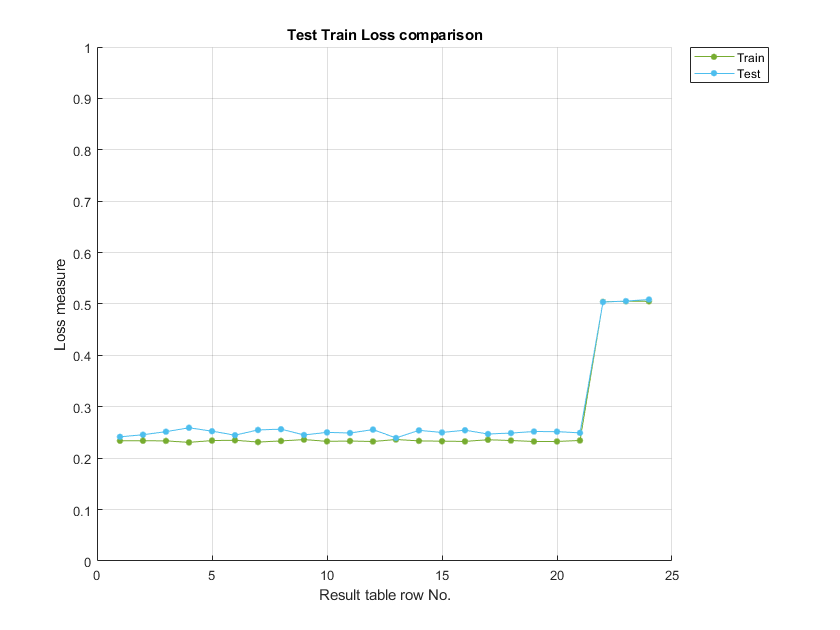

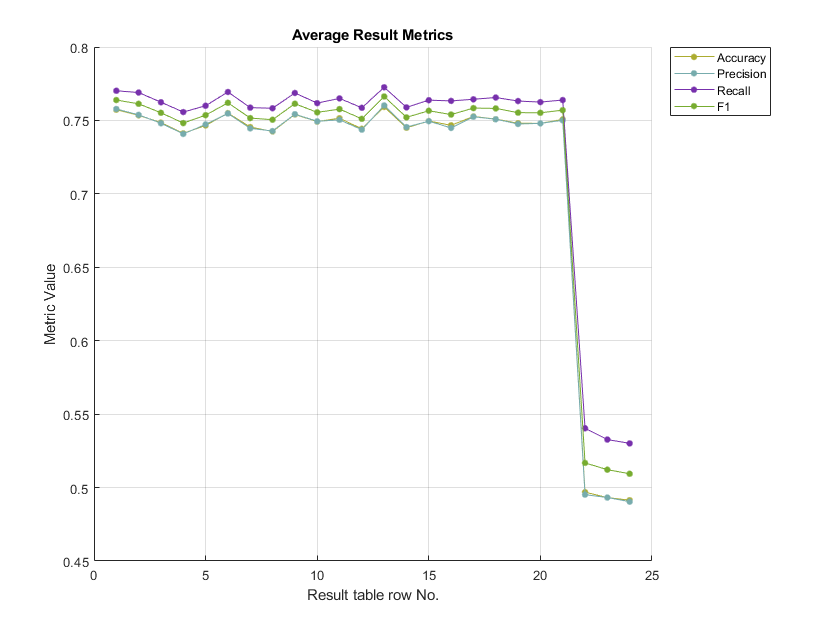

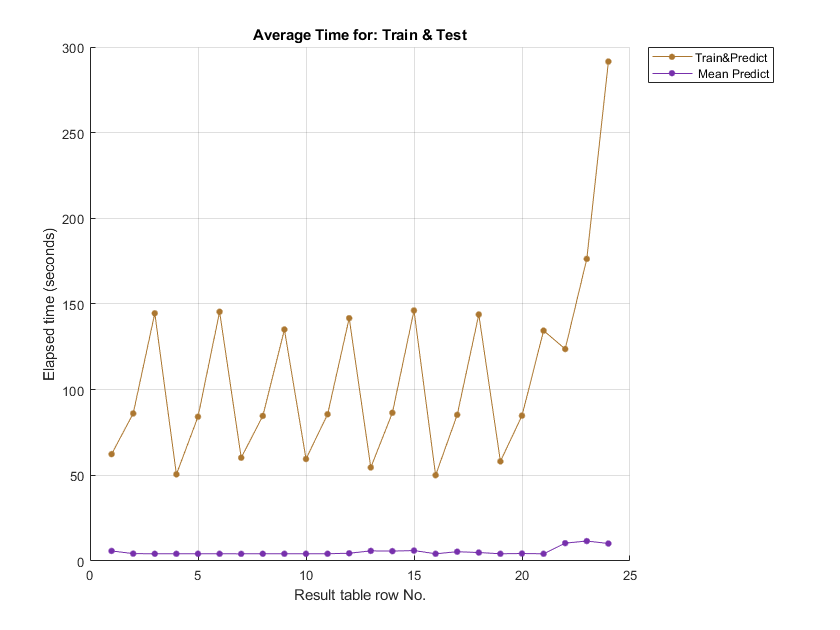

    distributionName    smootherType    Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}         {'box'}        0.2           2                 2                0.2

bestBox = 1×14 table
    distributionName    smootherType    Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}         {'box'}       0.11           2                

    distributionName      smootherType       Width      numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ________________    ________    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}       {'triangle'    }    0.098351          2                

### References

[1] [Multi-Class Metrics Made Simple, Part I: Precision and Recall | by Boaz Shmueli | Towards Data Science](https://towardsdatascience.com/multi-class-metrics-made-simple-part-i-precision-and-recall-9250280bddc2)

[2] [Multi-Class Metrics Made Simple, Part II: the F1-score | by Boaz Shmueli | Towards Data Science](https://towardsdatascience.com/multi-class-metrics-made-simple-part-ii-the-f1-score-ebe8b2c2ca1)

[3] Train multiclass naive Bayes model, fitcnb. MATLAB documentation. [https://www.mathworks.com/help/releases/R2020b/stats/fitcnb.html](https://www.mathworks.com/help/releases/R2020b/stats/fitcnb.html)